# Machine Learning: Programming Exercise 7

## *K*-Means Clustering and Principal Component Analysis

In this exercise, you will implement the *K*-means clustering algorithm and apply it to compress an image. In the second part, you will use principal component analysis to find a low-dimensional representation of face images.

### Files needed for this exercise

- `ex7.mlx` - MATLAB Live Script that steps you through the exercise

- `ex7data1.mat` - Example Dataset for PCA

- `ex7data2.mat` - Example Dataset for K-means

- `ex7faces.mat` - Faces Dataset

- bird small.png - Example Image

- `displayData.m` - Displays 2D data stored in a matrix

- `drawLine.m` - Draws a line over an exsiting figure

- `plotDataPoints.m` - Initialization for K-means centroids

- `plotProgresskMeans.m` - Plots each step of K-means as it proceeds

- `runkMeans.m` - Runs the K-means algorithm

- `submit.m` - Submission script that sends your solutions to our servers

- *`pca.m` - Perform principal component analysis

- *`projectData.m` - Projects a data set into a lower dimensional space

- *`recoverData.m` - Recovers the original data from the projection

- *`findClosestCentroids.m` - Find closest centroids (used in K-means)

- *`computeCentroids.m` - Compute centroid means (used in K-means)

- *`kMeansInitCentroids.m` - Initialization for K-means centroids

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex7' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                       computeCentroids.m      ex7_companion.mlx       featureNormalize.m      pca.m                   recoverData.m           
..                      displayData.m           ex7data1.mat            findClosestCentroids.m  plotDataPoints.m        runkMeans.m             
bird_small.mat          drawLine.m              ex7data2.mat            kMeansInitCentroids.m   plotProgresskMeans.m    submit.m                
bird_small.png          ex7.mlx                 ex7faces.mat            lib                     projectData.m           token.mat               



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. *K*-Means Clustering

In this this exercise, you will implement the *K*-means algorithm and use it for image compression. You will first start on an example 2D dataset that will help you gain an intuition of how the *K*-means algorithm works. After that, you wil use the *K*-means algorithm for image compression by reducing the number of colors that occur in an image to only those that are most common in that image.

### 1.1 Implementing *K*-means

The K-means algorithm is a method to automatically cluster similar data examples together. Concretely, you are given a training set $\{x^{(1)},\ldots x^{(m)}\}$ (where $x^{(i)}\in \mathbb{R}^n$), and want to group the data into a few cohesive 'clusters'. The intuition behind *K*-means is an iterative procedure that starts by guessing the initial centroids, and then refines this guess by repeatedly assigning examples to their closest centroids and then recomputing the centroids based on the assignments.

    The *K*-means algorithm is as follows:

The inner-loop of the algorithm repeatedly carries out two steps: 

- Assigning each training example $x^{(i)}$ to its closest centroid

- Recomputing the mean of each centroid using the points assigned to it. 

The *K*-means algorithm will always converge to some final set of means for the centroids. Note that the converged solution may not always be ideal and depends on the initial setting of the centroids. Therefore, in practice the K-means algorithm is usually run a few times with dierent random initializations. One way to choose between these different solutions from different random initializations is to choose the one with the lowest cost function value (distortion). You will implement the two phases of the K-means algorithm separately in the next sections.

#### 1.1.1 Finding closest centroids

In the 'cluster assignment' phase of the *K*-means algorithm, the algorithm assigns every training example $x^{(i)}$ to its closest centroid, given the current positions of centroids. Specically, for every example $i$ we set 


$$c^{(i)} :=j \quad\text{that minimizes}\quad\left||x^{(i)}-\mu_j\right||^2,$$


where $c^{(i)}$ is the index of the centroid that is closest to $x^{(i)}$, and $\mu_j$ is the position (value) of the $j$-th centroid. Note that $c^{(i)}$ corresponds to `idx(i)` in the starter code.

    Your task is to complete the code in `findClosestCentroids.m`. This function takes the data matrix `X` and the locations of all centroids inside centroids and should output a one-dimensional array `idx` that holds the index (a value in $\{1,\ldots,K\}$, where $K$ is total number of centroids) of the closest centroid to every training example. You can implement this using a loop over every training example and every centroid. 

    Once you have completed the code in `findClosestCentroids.m`, the code below will run your code and you should see the output `[1 3 2]` corresponding to the centroid assignments for the first 3 examples.

% Load an example dataset that we will be using
load('ex7data2.mat');

% Select an initial set of centroids
K = 3; % 3 Centroids
initial_centroids = [3 3; 6 2; 8 5];

% Find the closest centroids for the examples using the initial_centroids
idx = findClosestCentroids(X, initial_centroids);

minimum = 3.9251

minimum = 10.3079

minimum = 7.9564

minimum = 5.5222

minimum = 11.3244

minimum = 1.7906

minimum = 2.6084

minimum = 3.8170

minimum = 6.8050

minimum = 3.1071

minimum = 4.8109

minimum = 3.3876

minimum = 3.2646

minimum = 6.4179

minimum = 5.6491

minimum = 5.3402

minimum = 5.8619

minimum = 10.2102

minimum = 3.5354

minimum = 5.1052

minimum = 2.8190

minimum = 8.9500

minimum = 3.3993

minimum = 9.8425

minimum = 3.8666

minimum = 7.7891

minimum = 10.4839

minimum = 7.3341

minimum = 5.9531

minimum = 5.1292

minimum = 8.1574

minimum = 8.0929

minimum = 5.0296

minimum = 4.9387

minimum = 4.5144

minimum = 3.7031

minimum = 6.8073

minimum = 4.7992

minimum = 5.3193

minimum = 6.2273

minimum = 6.5383

minimum = 4.2908

minimum = 5.3408

minimum = 6.8952

minimum = 3.8761

minimum = 6.4801

minimum = 10.8480

minimum = 6.3520

minimum = 7.8057

minimum = 3.4896

minimum = 3.6741

minimum = 4.2779

minimum = 4.1414

minimum = 5.9498

minimum = 4.8002

minimum = 5.0211

minimum = 4.4015

minimum = 5.6685

minimum = 3.4983

minimum = 11.3703

minimum = 6.8108

minimum = 4.2783

minimum = 7.7823

minimum = 2.7576

minimum = 7.8169

minimum = 4.6601

minimum = 11.9827

minimum = 2.9534

minimum = 8.4118

minimum = 3.1529

minimum = 18.0395

minimum = 4.8055

minimum = 5.4630

minimum = 3.5127

minimum = 5.7118

minimum = 7.9513

minimum = 5.3439

minimum = 4.4185

minimum = 5.7274

minimum = 6.5745

minimum = 6.5114

minimum = 10.9279

minimum = 9.9534

minimum = 13.7058

minimum = 4.5396

minimum = 6.7802

minimum = 4.0640

minimum = 9.8483

minimum = 4.6889

minimum = 5.0563

minimum = 3.9185

minimum = 10.1177

minimum = 6.7615

minimum = 4.0322

minimum = 4.4590

minimum = 13.2438

minimum = 5.0899

minimum = 4.3788

minimum = 5.2116

minimum = 5.8802

minimum = 6.6279

minimum = 6.1961

minimum = 7.1885

minimum = 5.2298

minimum = 2.0432

minimum = 4.4176

minimum = 6.2102

minimum = 5.6983

minimum = 4.9524

minimum = 4.0974

minimum = 6.8202

minimum = 5.6041

minimum = 4.7608

minimum = 8.6335

minimum = 3.5321

minimum = 5.0584

minimum = 7.5088

minimum = 5.7636

minimum = 4.3660

minimum = 4.0315

minimum = 2.9356

minimum = 4.4299

minimum = 1.6389

minimum = 4.9371

minimum = 3.0643

minimum = 4.3807

minimum = 3.7334

minimum = 8.0989

minimum = 4.5905

minimum = 3.8622

minimum = 5.9602

minimum = 4.2378

minimum = 7.1971

minimum = 5.9398

minimum = 3.6632

minimum = 7.4894

minimum = 3.9327

minimum = 3.9083

minimum = 4.8335

minimum = 3.7110

minimum = 3.8562

minimum = 5.1845

minimum = 3.9332

minimum = 5.6398

minimum = 4.2482

minimum = 3.5327

minimum = 4.1875

minimum = 5.6102

minimum = 5.5426

minimum = 2.3015

minimum = 7.8874

minimum = 5.6875

minimum = 3.0091

minimum = 3.0451

minimum = 2.7024

minimum = 2.5490

minimum = 9.1743

minimum = 6.5712

minimum = 3.4848

minimum = 4.7901

minimum = 3.9526

minimum = 8.4662

minimum = 6.3952

minimum = 5.3300

minimum = 3.8966

minimum = 3.9266

minimum = 5.0997

minimum = 3.4350

minimum = 6.0413

minimum = 4.0606

minimum = 3.5563

minimum = 5.3698

minimum = 3.2417

minimum = 3.7797

minimum = 4.6450

minimum = 5.7686

minimum = 3.5906

minimum = 3.2602

minimum = 5.6522

minimum = 7.4528

minimum = 4.2063

minimum = 5.2352

minimum = 7.0212

minimum = 5.3011

minimum = 2.5155

minimum = 4.1846

minimum = 4.2755

minimum = 4.9448

minimum = 3.6380

minimum = 3.9725

minimum = 5.5231

minimum = 6.9704

minimum = 4.8522

minimum = 5.5183

minimum = 6.9013

minimum = 5.4061

minimum = 2.8659

minimum = 3.4007

minimum = 3.6059

minimum = 7.2507

minimum = 5.6139

minimum = 2.6825

minimum = 5.2847

minimum = 3.6710

minimum = 7.1035

minimum = 2.9720

minimum = 3.8911

minimum = 2.7935

minimum = 7.4675

minimum = 3.3232

minimum = 4.8847

minimum = 4.2779

minimum = 12.1786

minimum = 3.1617

minimum = 4.2170

minimum = 11.8068

minimum = 3.6753

minimum = 9.1045

minimum = 0.5298

minimum = 9.3476

minimum = 0.9052

minimum = 14.2597

minimum = 2.0672

minimum = 7.0652

minimum = 0.6108

minimum = 6.9341

minimum = 1.1146

minimum = 10.1613

minimum = 1.6952

minimum = 18.0375

minimum = 2.4934

minimum = 6.7771

minimum = 1.9575

minimum = 5.6040

minimum = 1.7213

minimum = 2.9618

minimum = 2.2894

minimum = 19.8332

minimum = 4.1933

minimum = 2.6768

minimum = 13.2610

minimum = 1.5345

minimum = 11.5802

minimum = 0.4569

minimum = 18.4469

minimum = 2.2236

minimum = 10.3622

minimum = 0.5016

minimum = 6.2362

minimum = 0.4468

minimum = 7.1158

minimum = 1.0415

minimum = 12.9436

minimum = 1.5031

minimum = 22.6496

minimum = 4.4221

minimum = 3.4594

minimum = 13.2179

minimum = 1.7181

minimum = 7.6731

minimum = 1.3604

minimum = 9.0244

minimum = 0.5732

minimum = 11.5380

minimum = 0.5662

minimum = 7.5204

minimum = 1.2860

minimum = 2.6559

minimum = 2.5432

minimum = 5.4554

minimum = 1.5219

minimum = 5.6644

minimum = 1.0604

minimum = 4.1514

minimum = 1.7844

minimum = 6.5097

minimum = 2.0088

minimum = 9.3450

minimum = 0.6539

minimum = 5.1885

minimum = 0.7927

minimum = 7.4835

minimum = 0.8412

minimum = 14.3000

minimum = 1.7269

minimum = 12.0157

minimum = 2.0316

minimum = 11.5665

minimum = 0.9652

minimum = 8.1835

minimum = 1.0110

minimum = 11.9137

minimum = 1.5590

minimum = 5.6411

minimum = 1.8287

minimum = 8.4566

minimum = 1.8248

minimum = 1.0030

minimum = 10.8173

minimum = 1.4582

minimum = 1.4878

minimum = 5.4121

minimum = 1.5214

minimum = 17.5701

minimum = 3.3666

minimum = 3.2075

minimum = 20.2299

minimum = 2.9407

minimum = 19.5781

minimum = 4.1594

minimum = 2.6579

minimum = 4.0981

minimum = 1.9258

minimum = 5.4024

minimum = 1.1345

minimum = 8.3215

minimum = 1.4954

minimum = 9.3277

minimum = 0.4680

minimum = 8.5051

minimum = 0.7409

minimum = 13.6614

minimum = 1.2754

minimum = 9.1374

minimum = 0.5243

minimum = 15.4629

minimum = 2.2988

minimum = 11.2215

minimum = 1.8252

minimum = 10.5576

minimum = 0.6858

minimum = 6.7081

minimum = 1.7346

minimum = 11.7180

minimum = 0.6226

minimum = 14.4731

minimum = 2.0230

minimum = 17.8552

minimum = 2.0121

minimum = 12.4015

minimum = 0.7901

minimum = 2.6888

minimum = 21.6860

minimum = 3.4977

minimum = 6.4023

minimum = 0.6430

minimum = 13.1815

minimum = 1.4279

minimum = 0.3103

minimum = 27.4153

minimum = 5.0288

minimum = 3.8395

minimum = 1.8943

minimum = 5.9224

minimum = 0.5983

minimum = 7.2816

minimum = 0.9933

minimum = 11.2912

minimum = 0.1338

minimum = 4.2729

minimum = 1.4702

minimum = 15.1115

minimum = 1.5739

minimum = 1.4222

minimum = 8.8519

minimum = 1.0531

minimum = 9.7218

minimum = 0.3917

minimum = 7.4219

minimum = 1.1673

minimum = 1.8868

minimum = 10.8880

minimum = 0.6871

minimum = 5.8844

minimum = 5.2770

minimum = 13.0077

minimum = 2.2355

minimum = 7.8568

minimum = 1.7158

minimum = 13.8979

minimum = 1.5388

minimum = 13.6026

minimum = 0.5793

minimum = 10.5214

minimum = 0.5847

minimum = 10.3899

minimum = 0.7034

minimum = 7.7412

minimum = 1.2140

minimum = 13.2021

minimum = 0.9443

minimum = 4.8269

minimum = 1.7909

minimum = 8.3122

minimum = 1.5919

minimum = 8.3949

minimum = 0.8181

minimum = 7.0135

minimum = 0.5033

minimum = 6.9284

minimum = 1.2330

minimum = 6.2770

minimum = 1.4989

minimum = 12.3269

minimum = 0.5359

minimum = 18.6585

minimum = 3.6021

minimum = 3.1100

minimum = 15.9361

minimum = 1.9583

minimum = 3.3811

minimum = 1.9872

minimum = 9.7410

minimum = 0.7445

minimum = 11.6159

fprintf('Closest centroids for the first 3 examples: %d %d %d', idx(1:3))

Closest centroids for the first 3 examples: 1 3 2

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 1.1.2 Computing centroid means

Given assignments of every point to a centroid, the second phase of the algorithm recomputes, for each centroid, the mean of the points that were assigned to it. Specically, for every centroid $k$ we set


$$\mu_k := \frac{1}{|C_k|}\sum_{i\in C_k}{x^{(i)}}$$


where $C_k$ is the set of examples that are assigned to centroid $k$. Concretely, if two examples say $x^{(3)}$ and $x^{(5)}$ are assigned to centroid $k = 2$, then you should update $\mu_2 = \frac{1}{2} (x^{(3)} + x^{(5)})$. You should now complete the code in `computeCentroids.m`. You can implement this function using a loop over the centroids. You can also use a loop over the examples; but if you can use a vectorized implementation that does not use such a loop, your code may run faster. Once you have completed the code in `computeCentroids.m`, the code below will run your code and output the centroids after the first step of *K*-means. The centroids should be:

- `[ 2.428301 3.157924 ]`

- `[ 5.813503 2.633656 ]`

- `[ 7.119387 3.616684 ]`

% Compute means based on the closest centroids found in the previous part.
centroids = computeCentroids(X, idx, K);
fprintf('Centroids computed after initial finding of closest centroids: \n %f %f \n %f %f\n %f %f' , centroids');

Centroids computed after initial finding of closest centroids: 
 2.428301 3.157924 
 5.813503 2.633656
 7.119387 3.616684

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.2 K-means on example dataset

After you have completed the two functions (`findClosestCentroids` and `computeCentroids`), the code below will run the *K*-means algorithm on a toy 2D dataset to help you understand how *K*-means works. Your functions are called from inside the `runKmeans.m` script. We encourage you to take a look at the function to understand how it works. Notice that the code calls the two functions you implemented in a loop.

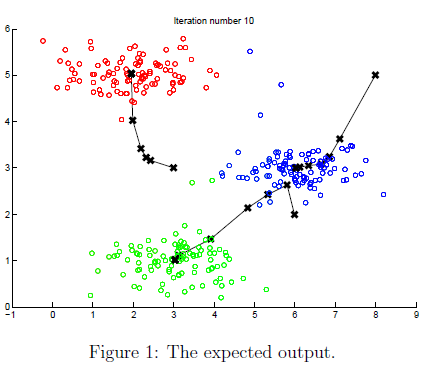

    When you run the next step, the *K*-means code will produce a visualization that steps you through the progress of the algorithm at each iteration. 

**At the command line**, **press enter multiple times to see how each step of the *****K*****-means algorithm changes the centroids and cluster assignments.** 

At the end, your figure should look as the one displayed in Figure 1.

% Load an example dataset
load('ex7data2.mat');
% Settings for running K-Means
max_iters = 10;

For consistency, here we set centroids to specific values but in practice you want to generate them automatically, such as by setting them to be random examples (as can be seen in `kMeansInitCentroids`).

initial_centroids = [3 3; 6 2; 8 5];

% Run K-Means algorithm. The 'true' at the end tells our function to plot the progress of K-Means
figure('visible','on'); hold on; 
plotProgresskMeans(X, initial_centroids, initial_centroids, idx, K, 1); 
xlabel('Press ENTER in command window to advance','FontWeight','bold','FontSize',14)
[~, ~] = runkMeans(X, initial_centroids, max_iters, true);

K-Means iteration 1/10...


minimum = 3.9251

minimum = 10.3079

minimum = 7.9564

minimum = 5.5222

minimum = 11.3244

minimum = 1.7906

minimum = 2.6084

minimum = 3.8170

minimum = 6.8050

minimum = 3.1071

minimum = 4.8109

minimum = 3.3876

minimum = 3.2646

minimum = 6.4179

minimum = 5.6491

minimum = 5.3402

minimum = 5.8619

minimum = 10.2102

minimum = 3.5354

minimum = 5.1052

minimum = 2.8190

minimum = 8.9500

minimum = 3.3993

minimum = 9.8425

minimum = 3.8666

minimum = 7.7891

minimum = 10.4839

minimum = 7.3341

minimum = 5.9531

minimum = 5.1292

minimum = 8.1574

minimum = 8.0929

minimum = 5.0296

minimum = 4.9387

minimum = 4.5144

minimum = 3.7031

minimum = 6.8073

minimum = 4.7992

minimum = 5.3193

minimum = 6.2273

minimum = 6.5383

minimum = 4.2908

minimum = 5.3408

minimum = 6.8952

minimum = 3.8761

minimum = 6.4801

minimum = 10.8480

minimum = 6.3520

minimum = 7.8057

minimum = 3.4896

minimum = 3.6741

minimum = 4.2779

minimum = 4.1414

minimum = 5.9498

minimum = 4.8002

minimum = 5.0211

minimum = 4.4015

minimum = 5.6685

minimum = 3.4983

minimum = 11.3703

minimum = 6.8108

minimum = 4.2783

minimum = 7.7823

minimum = 2.7576

minimum = 7.8169

minimum = 4.6601

minimum = 11.9827

minimum = 2.9534

minimum = 8.4118

minimum = 3.1529

minimum = 18.0395

minimum = 4.8055

minimum = 5.4630

minimum = 3.5127

minimum = 5.7118

minimum = 7.9513

minimum = 5.3439

minimum = 4.4185

minimum = 5.7274

minimum = 6.5745

minimum = 6.5114

minimum = 10.9279

minimum = 9.9534

minimum = 13.7058

minimum = 4.5396

minimum = 6.7802

minimum = 4.0640

minimum = 9.8483

minimum = 4.6889

minimum = 5.0563

minimum = 3.9185

minimum = 10.1177

minimum = 6.7615

minimum = 4.0322

minimum = 4.4590

minimum = 13.2438

minimum = 5.0899

minimum = 4.3788

minimum = 5.2116

minimum = 5.8802

minimum = 6.6279

minimum = 6.1961

minimum = 7.1885

minimum = 5.2298

minimum = 2.0432

minimum = 4.4176

minimum = 6.2102

minimum = 5.6983

minimum = 4.9524

minimum = 4.0974

minimum = 6.8202

minimum = 5.6041

minimum = 4.7608

minimum = 8.6335

minimum = 3.5321

minimum = 5.0584

minimum = 7.5088

minimum = 5.7636

minimum = 4.3660

minimum = 4.0315

minimum = 2.9356

minimum = 4.4299

minimum = 1.6389

minimum = 4.9371

minimum = 3.0643

minimum = 4.3807

minimum = 3.7334

minimum = 8.0989

minimum = 4.5905

minimum = 3.8622

minimum = 5.9602

minimum = 4.2378

minimum = 7.1971

minimum = 5.9398

minimum = 3.6632

minimum = 7.4894

minimum = 3.9327

minimum = 3.9083

minimum = 4.8335

minimum = 3.7110

minimum = 3.8562

minimum = 5.1845

minimum = 3.9332

minimum = 5.6398

minimum = 4.2482

minimum = 3.5327

minimum = 4.1875

minimum = 5.6102

minimum = 5.5426

minimum = 2.3015

minimum = 7.8874

minimum = 5.6875

minimum = 3.0091

minimum = 3.0451

minimum = 2.7024

minimum = 2.5490

minimum = 9.1743

minimum = 6.5712

minimum = 3.4848

minimum = 4.7901

minimum = 3.9526

minimum = 8.4662

minimum = 6.3952

minimum = 5.3300

minimum = 3.8966

minimum = 3.9266

minimum = 5.0997

minimum = 3.4350

minimum = 6.0413

minimum = 4.0606

minimum = 3.5563

minimum = 5.3698

minimum = 3.2417

minimum = 3.7797

minimum = 4.6450

minimum = 5.7686

minimum = 3.5906

minimum = 3.2602

minimum = 5.6522

minimum = 7.4528

minimum = 4.2063

minimum = 5.2352

minimum = 7.0212

minimum = 5.3011

minimum = 2.5155

minimum = 4.1846

minimum = 4.2755

minimum = 4.9448

minimum = 3.6380

minimum = 3.9725

minimum = 5.5231

minimum = 6.9704

minimum = 4.8522

minimum = 5.5183

minimum = 6.9013

minimum = 5.4061

minimum = 2.8659

minimum = 3.4007

minimum = 3.6059

minimum = 7.2507

minimum = 5.6139

minimum = 2.6825

minimum = 5.2847

minimum = 3.6710

minimum = 7.1035

minimum = 2.9720

minimum = 3.8911

minimum = 2.7935

minimum = 7.4675

minimum = 3.3232

minimum = 4.8847

minimum = 4.2779

minimum = 12.1786

minimum = 3.1617

minimum = 4.2170

minimum = 11.8068

minimum = 3.6753

minimum = 9.1045

minimum = 0.5298

minimum = 9.3476

minimum = 0.9052

minimum = 14.2597

minimum = 2.0672

minimum = 7.0652

minimum = 0.6108

minimum = 6.9341

minimum = 1.1146

minimum = 10.1613

minimum = 1.6952

minimum = 18.0375

minimum = 2.4934

minimum = 6.7771

minimum = 1.9575

minimum = 5.6040

minimum = 1.7213

minimum = 2.9618

minimum = 2.2894

minimum = 19.8332

minimum = 4.1933

minimum = 2.6768

minimum = 13.2610

minimum = 1.5345

minimum = 11.5802

minimum = 0.4569

minimum = 18.4469

minimum = 2.2236

minimum = 10.3622

minimum = 0.5016

minimum = 6.2362

minimum = 0.4468

minimum = 7.1158

minimum = 1.0415

minimum = 12.9436

minimum = 1.5031

minimum = 22.6496

minimum = 4.4221

minimum = 3.4594

minimum = 13.2179

minimum = 1.7181

minimum = 7.6731

minimum = 1.3604

minimum = 9.0244

minimum = 0.5732

minimum = 11.5380

minimum = 0.5662

minimum = 7.5204

minimum = 1.2860

minimum = 2.6559

minimum = 2.5432

minimum = 5.4554

minimum = 1.5219

minimum = 5.6644

minimum = 1.0604

minimum = 4.1514

minimum = 1.7844

minimum = 6.5097

minimum = 2.0088

minimum = 9.3450

minimum = 0.6539

minimum = 5.1885

minimum = 0.7927

minimum = 7.4835

minimum = 0.8412

minimum = 14.3000

minimum = 1.7269

minimum = 12.0157

minimum = 2.0316

minimum = 11.5665

minimum = 0.9652

minimum = 8.1835

minimum = 1.0110

minimum = 11.9137

minimum = 1.5590

minimum = 5.6411

minimum = 1.8287

minimum = 8.4566

minimum = 1.8248

minimum = 1.0030

minimum = 10.8173

minimum = 1.4582

minimum = 1.4878

minimum = 5.4121

minimum = 1.5214

minimum = 17.5701

minimum = 3.3666

minimum = 3.2075

minimum = 20.2299

minimum = 2.9407

minimum = 19.5781

minimum = 4.1594

minimum = 2.6579

minimum = 4.0981

minimum = 1.9258

minimum = 5.4024

minimum = 1.1345

minimum = 8.3215

minimum = 1.4954

minimum = 9.3277

minimum = 0.4680

minimum = 8.5051

minimum = 0.7409

minimum = 13.6614

minimum = 1.2754

minimum = 9.1374

minimum = 0.5243

minimum = 15.4629

minimum = 2.2988

minimum = 11.2215

minimum = 1.8252

minimum = 10.5576

minimum = 0.6858

minimum = 6.7081

minimum = 1.7346

minimum = 11.7180

minimum = 0.6226

minimum = 14.4731

minimum = 2.0230

minimum = 17.8552

minimum = 2.0121

minimum = 12.4015

minimum = 0.7901

minimum = 2.6888

minimum = 21.6860

minimum = 3.4977

minimum = 6.4023

minimum = 0.6430

minimum = 13.1815

minimum = 1.4279

minimum = 0.3103

minimum = 27.4153

minimum = 5.0288

minimum = 3.8395

minimum = 1.8943

minimum = 5.9224

minimum = 0.5983

minimum = 7.2816

minimum = 0.9933

minimum = 11.2912

minimum = 0.1338

minimum = 4.2729

minimum = 1.4702

minimum = 15.1115

minimum = 1.5739

minimum = 1.4222

minimum = 8.8519

minimum = 1.0531

minimum = 9.7218

minimum = 0.3917

minimum = 7.4219

minimum = 1.1673

minimum = 1.8868

minimum = 10.8880

minimum = 0.6871

minimum = 5.8844

minimum = 5.2770

minimum = 13.0077

minimum = 2.2355

minimum = 7.8568

minimum = 1.7158

minimum = 13.8979

minimum = 1.5388

minimum = 13.6026

minimum = 0.5793

minimum = 10.5214

minimum = 0.5847

minimum = 10.3899

minimum = 0.7034

minimum = 7.7412

minimum = 1.2140

minimum = 13.2021

minimum = 0.9443

minimum = 4.8269

minimum = 1.7909

minimum = 8.3122

minimum = 1.5919

minimum = 8.3949

minimum = 0.8181

minimum = 7.0135

minimum = 0.5033

minimum = 6.9284

minimum = 1.2330

minimum = 6.2770

minimum = 1.4989

minimum = 12.3269

minimum = 0.5359

minimum = 18.6585

minimum = 3.6021

minimum = 3.1100

minimum = 15.9361

minimum = 1.9583

minimum = 3.3811

minimum = 1.9872

minimum = 9.7410

minimum = 0.7445

minimum = 11.6159

Press enter to continue.


set(gcf,'visible','off'); hold off;

### 1.3 Random initialization

The initial assignments of centroids for the example dataset were designed so that you will see the same figure as in Figure 1. In practice, a good strategy for initializing the centroids is to select random examples from the training set. In this part of the exercise, you should complete the function `kMeansInitCentroids.m` with the following code:

The code above first randomly permutes the indices of the examples (using randperm). Then, it selects the first $K$ examples based on the random permutation of the indices. This allows the examples to be selected at random without the risk of selecting the same example twice.

*You do not need to make any submissions for this part of the exercise.*

### 1.4 Image compression with *K*-means

In this exercise, you will apply *K*-means to image compression. In a straightforward 24-bit color representation of an image, each pixel is represented as three 8-bit unsigned integers (ranging from 0 to 255) that specify the red, green and blue intensity values. This encoding is often refered to as the RGB encoding. Our image contains thousands of colors, and in this part of the exercise, you will reduce the number of colors to 16 colors. By making this reduction, it is possible to represent (compress) the photo in an efficient way. Specifically, you only need to store the RGB values of the 16 selected colors, and for each pixel in the image you now need to only store the index of the color at that location (where only 4 bits are necessary to represent 16 possibilities). 

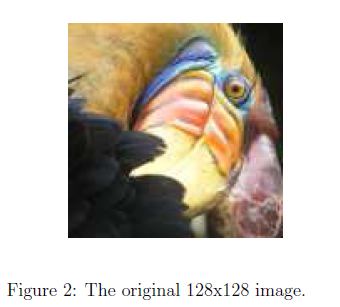

    In this exercise, you will use the *K*-means algorithm to select the 16 colors that will be used to represent the compressed image. Concretely, you will treat every pixel in the original image as a data example and use the *K*-means algorithm to find the 16 colors that best group (cluster) the pixels in the 3-dimensional RGB space. Once you have computed the cluster centroids on the image, you will then use the 16 colors to replace the pixels in the original image.

**The provided photo used in this exercise belongs to Frank Wouters and is used with his permission.*

#### 1.4.1 *K*-means on pixels

In MATLAB, images can be read in as follows:

This creates a three-dimensional matrix `A` whose first two indices identify a pixel position and whose last index represents red, green, or blue. For example, `A(50,33,3)` gives the blue intensity of the pixel at row 50 and column 33. The code below first loads the image, and then reshapes it to create an m by 3 matrix of pixel colors (where $m = 16384 = 128\times128$), and calls your *K*-means function on it.

%  Load an image of a bird
A = double(imread('bird_small.png'));
A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);

Reshape the image into an Nx3 matrix where N = number of pixels. Each row will contain the Red, Green and Blue pixel values. This gives us our dataset matrix X that we will use K-Means on.

X = reshape(A, img_size(1) * img_size(2), 3);

Run your K-Means algorithm on this data. You should try different values of K and max_iters here:

K = 16;
max_iters = 10;

When using K-Means, it is important the initialize the centroids randomly. You should complete the code in `kMeansInitCentroids.m` before proceeding

initial_centroids = kMeansInitCentroids(X, K);
% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

K-Means iteration 1/10...


minimum = 1.0479

minimum = 0.0830

minimum = 7.9969e-04

minimum = 1.2232

minimum = 0.0411

minimum = 0.0076

minimum = 1.2125

minimum = 0.0375

minimum = 0.0075

minimum = 1.1007

minimum = 0.0520

minimum = 0.0024

minimum = 0.9975

minimum = 0.0817

minimum = 4.9212e-04

minimum = 1.0876

minimum = 0.0623

minimum = 7.8431e-04

minimum = 1.0520

minimum = 0.0656

minimum = 4.1522e-04

minimum = 1.0395

minimum = 0.0743

minimum = 0

minimum = 1.2510

minimum = 0.0414

minimum = 0.0098

minimum = 1.2670

minimum = 0.0304

minimum = 0.0126

minimum = 1.2909

minimum = 0.0176

minimum = 1.1705

minimum = 0.0344

minimum = 0.0082

minimum = 1.1573

minimum = 0.0409

minimum = 0.0050

minimum = 1.1942

minimum = 0.0431

minimum = 0.0056

minimum = 1.1958

minimum = 0.0366

minimum = 0.0069

minimum = 1.2645

minimum = 0.0292

minimum = 0.0124

minimum = 1.1221

minimum = 0.0752

minimum = 0.0034

minimum = 1.1755

minimum = 0.0372

minimum = 0.0064

minimum = 1.1956

minimum = 0.0288

minimum = 0.0111

minimum = 1.1343

minimum = 0.0499

minimum = 0.0026

minimum = 1.1416

minimum = 0.0373

minimum = 0.0076

minimum = 1.1492

minimum = 0.0351

minimum = 0.0091

minimum = 1.1505

minimum = 0.0304

minimum = 0.0169

minimum = 1.1308

minimum = 0.0331

minimum = 0.0190

minimum = 1.1215

minimum = 0.0346

minimum = 0.0220

minimum = 1.1180

minimum = 0.0355

minimum = 0.0248

minimum = 0.9794

minimum = 0.0653

minimum = 0.0172

minimum = 0.8917

minimum = 0.0949

minimum = 0.0109

minimum = 1.0589

minimum = 0.0524

minimum = 0.0052

minimum = 1.0248

minimum = 0.0566

minimum = 0.0088

minimum = 0.9979

minimum = 0.0607

minimum = 0.0166

minimum = 1.0062

minimum = 0.0593

minimum = 0.0261

minimum = 1.0866

minimum = 0.0416

minimum = 0.0266

minimum = 0.7677

minimum = 0.1432

minimum = 0.0579

minimum = 0.0651

minimum = 0.0615

minimum = 0.0508

minimum = 0.0092

minimum = 0.2865

minimum = 0.0107

minimum = 0.8025

minimum = 0.1233

minimum = 0.0284

minimum = 0.8133

minimum = 0.1181

minimum = 0.0307

minimum = 0.3505

minimum = 0.0170

minimum = 0.0166

minimum = 0.0836

minimum = 0.0642

minimum = 0.0486

minimum = 0.0291

minimum = 0.0201

minimum = 0.0761

minimum = 0.0758

minimum = 0.0586

minimum = 0.0312

minimum = 0.0181

minimum = 0.0685

minimum = 0.0559

minimum = 0.0217

minimum = 0.0128

minimum = 0.0244

minimum = 0.0178

minimum = 8.6121e-04

minimum = 0.1363

minimum = 0.0289

minimum = 0.0219

minimum = 0.5373

minimum = 0.2673

minimum = 0.0641

minimum = 0.0553

minimum = 0.0497

minimum = 0.2319

minimum = 0.0235

minimum = 0.0132

minimum = 0.2732

minimum = 0.0396

minimum = 0.0270

minimum = 0.2567

minimum = 0.0287

minimum = 0.0182

minimum = 0.1464

minimum = 0.0650

minimum = 0.0461

minimum = 0.0957

minimum = 0.0666

minimum = 0.0495

minimum = 0.0397

minimum = 0.0279

minimum = 0.0788

minimum = 0.0760

minimum = 0.0585

minimum = 0.0337

minimum = 0.0195

minimum = 0.0313

minimum = 0.0198

minimum = 0.0021

minimum = 0.0139

minimum = 0.0017

minimum = 0.0164

minimum = 0.0161

minimum = 7.6894e-04

minimum = 0.0230

minimum = 0.0127

minimum = 4.4598e-04

minimum = 0.0297

minimum = 0.0094

minimum = 0.0010

minimum = 0.0307

minimum = 0.0082

minimum = 9.0734e-04

minimum = 0.0096

minimum = 0.0048

minimum = 7.6894e-05

minimum = 0.0023

minimum = 6.6128e-04

minimum = 1.9992e-04

minimum = 0.0019

minimum = 8.7659e-04

minimum = 3.2295e-04

minimum = 0.0015

minimum = 0.0012

minimum = 4.4598e-04

minimum = 0.0019

minimum = 0.0011

minimum = 4.9212e-04

minimum = 0.0020

minimum = 9.3810e-04

minimum = 2.9220e-04

minimum = 7.8431e-04

minimum = 7.6894e-04

minimum = 0.0021

minimum = 8.3045e-04

minimum = 4.6136e-04

minimum = 0.0046

minimum = 3.0757e-05

minimum = 0.0030

minimum = 3.6909e-04

minimum = 9.2272e-05

minimum = 0.0030

minimum = 3.3833e-04

minimum = 6.1515e-05

minimum = 0.0023

minimum = 6.3053e-04

minimum = 2.6144e-04

minimum = 0.0023

minimum = 6.9204e-04

minimum = 3.2295e-04

minimum = 0.0035

minimum = 2.1530e-04

minimum = 1.2303e-04

minimum = 0.0033

minimum = 2.6144e-04

minimum = 1.6917e-04

minimum = 0.0030

minimum = 3.9985e-04

minimum = 3.0757e-04

minimum = 0.0032

minimum = 2.6144e-04

minimum = 7.6894e-05

minimum = 0.0033

minimum = 2.6144e-04

minimum = 7.6894e-05

minimum = 0.0035

minimum = 2.1530e-04

minimum = 3.0757e-05

minimum = 0.0046

minimum = 9.2272e-05

minimum = 0.0050

minimum = 4.6136e-05

minimum = 0.0032

minimum = 2.6144e-04

minimum = 7.6894e-05

minimum = 0.0028

minimum = 4.4598e-04

minimum = 2.6144e-04

minimum = 0.0028

minimum = 5.3825e-04

minimum = 7.6894e-05

minimum = 0.0038

minimum = 1.9992e-04

minimum = 1.5379e-05

minimum = 0.0053

minimum = 0

minimum = 0.0035

minimum = 2.1530e-04

minimum = 3.0757e-05

minimum = 0.0021

minimum = 8.6121e-04

minimum = 2.1530e-04

minimum = 0.0053

minimum = 3.0757e-05

minimum = 0.0067

minimum = 9.2272e-05

minimum = 0.0104

minimum = 8.7659e-04

minimum = 0.0086

minimum = 4.4598e-04

minimum = 0.0063

minimum = 7.6894e-05

minimum = 0.0067

minimum = 9.2272e-05

minimum = 0.0027

minimum = 8.7659e-04

minimum = 7.8431e-04

minimum = 0.0014

minimum = 7.0742e-04

minimum = 0.0030

minimum = 3.3833e-04

minimum = 1.5379e-04

minimum = 0.0046

minimum = 9.2272e-05

minimum = 0.0035

minimum = 2.7682e-04

minimum = 9.2272e-05

minimum = 0.0059

minimum = 9.2272e-05

minimum = 0.0038

minimum = 2.6144e-04

minimum = 1.6917e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 2.1530e-04

minimum = 7.3818e-04

minimum = 0.0024

minimum = 7.8431e-04

minimum = 5.0750e-04

minimum = 2.7682e-04

minimum = 5.2288e-04

minimum = 0.0017

minimum = 0.0014

minimum = 9.0734e-04

minimum = 0.0038

minimum = 1.9992e-04

minimum = 0.0035

minimum = 2.1530e-04

minimum = 0.0025

minimum = 5.2288e-04

minimum = 1.5379e-04

minimum = 0.0030

minimum = 3.6909e-04

minimum = 9.2272e-05

minimum = 0.0046

minimum = 3.0757e-05

minimum = 0.0019

minimum = 9.0734e-04

minimum = 4.4598e-04

minimum = 0.0020

minimum = 9.3810e-04

minimum = 5.6901e-04

minimum = 0.0024

minimum = 6.9204e-04

minimum = 4.1522e-04

minimum = 0.0019

minimum = 9.3810e-04

minimum = 3.8447e-04

minimum = 0.0014

minimum = 7.9969e-04

minimum = 9.2272e-05

minimum = 1.3841e-04

minimum = 0

minimum = 1.8454e-04

minimum = 4.6136e-05

minimum = 9.2272e-05

minimum = 3.9985e-04

minimum = 6.3053e-04

minimum = 0.0021

minimum = 8.3045e-04

minimum = 2.7682e-04

minimum = 0.0030

minimum = 3.9985e-04

minimum = 2.1530e-04

minimum = 0.0028

minimum = 4.4598e-04

minimum = 2.6144e-04

minimum = 0.0022

minimum = 9.5348e-04

minimum = 6.7666e-04

minimum = 1.1744

minimum = 0.0521

minimum = 0.0046

minimum = 1.1836

minimum = 0.0419

minimum = 0.0053

minimum = 1.2064

minimum = 0.0401

minimum = 0.0067

minimum = 1.1002

minimum = 0.0545

minimum = 0.0022

minimum = 1.0801

minimum = 0.0597

minimum = 8.7659e-04

minimum = 1.1331

minimum = 0.0471

minimum = 0.0031

minimum = 1.1464

minimum = 0.0434

minimum = 0.0055

minimum = 1.1420

minimum = 0.0538

minimum = 0.0035

minimum = 1.2317

minimum = 0.0497

minimum = 0.0084

minimum = 1.2044

minimum = 0.0417

minimum = 0.0064

minimum = 1.1808

minimum = 0.0368

minimum = 0.0067

minimum = 1.1598

minimum = 0.0398

minimum = 0.0058

minimum = 1.2110

minimum = 0.0308

minimum = 0.0099

minimum = 1.2001

minimum = 0.0404

minimum = 0.0063

minimum = 1.1642

minimum = 0.0405

minimum = 0.0051

minimum = 1.2177

minimum = 0.0389

minimum = 0.0075

minimum = 1.1075

minimum = 0.0752

minimum = 0.0024

minimum = 1.1642

minimum = 0.0428

minimum = 0.0045

minimum = 1.1369

minimum = 0.0398

minimum = 0.0060

minimum = 1.1647

minimum = 0.0365

minimum = 0.0068

minimum = 1.1182

minimum = 0.0474

minimum = 0.0032

minimum = 1.1599

minimum = 0.0321

minimum = 0.0107

minimum = 1.2109

minimum = 0.0211

minimum = 1.1974

minimum = 0.0227

minimum = 1.1158

minimum = 0.0361

minimum = 0.0270

minimum = 1.0441

minimum = 0.0500

minimum = 0.0212

minimum = 1.0015

minimum = 0.0597

minimum = 0.0213

minimum = 0.9053

minimum = 0.0864

minimum = 0.0189

minimum = 0.9487

minimum = 0.0779

minimum = 0.0078

minimum = 1.0821

minimum = 0.0434

minimum = 0.0115

minimum = 1.0470

minimum = 0.0493

minimum = 0.0224

minimum = 1.0705

minimum = 0.0451

minimum = 0.0279

minimum = 1.0629

minimum = 0.0476

minimum = 0.0314

minimum = 0.2633

minimum = 0.0078

minimum = 0.0037

minimum = 0.0808

minimum = 0.0461

minimum = 0.0379

minimum = 0.0084

minimum = 0.6477

minimum = 0.1943

minimum = 0.1040

minimum = 0.0586

minimum = 0.8708

minimum = 0.0975

minimum = 0.0217

minimum = 0.8169

minimum = 0.1177

minimum = 0.0241

minimum = 0.3822

minimum = 0.0226

minimum = 0.0758

minimum = 0.0681

minimum = 0.0528

minimum = 0.0250

minimum = 0.0169

minimum = 0.0718

minimum = 0.0687

minimum = 0.0537

minimum = 0.0224

minimum = 0.0144

minimum = 0.0927

minimum = 0.0478

minimum = 0.0353

minimum = 0.0233

minimum = 0.0230

minimum = 0.2199

minimum = 0.0062

minimum = 0.0034

minimum = 0.8026

minimum = 0.1226

minimum = 0.0350

minimum = 0.5260

minimum = 0.2714

minimum = 0.0591

minimum = 0.2412

minimum = 0.0264

minimum = 0.0156

minimum = 0.2541

minimum = 0.0363

minimum = 0.0237

minimum = 0.2803

minimum = 0.0321

minimum = 0.0213

minimum = 0.1507

minimum = 0.0577

minimum = 0.0400

minimum = 0.1273

minimum = 0.0501

minimum = 0.0345

minimum = 0.0811

minimum = 0.0754

minimum = 0.0578

minimum = 0.0349

minimum = 0.0209

minimum = 0.0471

minimum = 0.0277

minimum = 0.0080

minimum = 0.0314

minimum = 0.0182

minimum = 0.0019

minimum = 0.0168

minimum = 0.0152

minimum = 7.8431e-04

minimum = 0.0171

minimum = 0.0152

minimum = 6.3053e-04

minimum = 0.0191

minimum = 0.0167

minimum = 8.7659e-04

minimum = 0.0151

minimum = 0.0020

minimum = 0.0018

minimum = 0.0012

minimum = 6.6128e-04

minimum = 0.0013

minimum = 6.3053e-04

minimum = 0.0014

minimum = 0.0013

minimum = 5.8439e-04

minimum = 0.0019

minimum = 9.0734e-04

minimum = 2.6144e-04

minimum = 0.0041

minimum = 9.2272e-05

minimum = 0.0016

minimum = 0.0012

minimum = 4.4598e-04

minimum = 0.0019

minimum = 0.0011

minimum = 5.0750e-04

minimum = 4.4598e-04

minimum = 6.3053e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 2.1530e-04

minimum = 0.0032

minimum = 3.2295e-04

minimum = 4.6136e-05

minimum = 0.0025

minimum = 5.8439e-04

minimum = 1.2303e-04

minimum = 0.0027

minimum = 5.0750e-04

minimum = 1.3841e-04

minimum = 0.0021

minimum = 8.3045e-04

minimum = 2.7682e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 3.0757e-04

minimum = 0.0013

minimum = 6.4591e-04

minimum = 0.0025

minimum = 5.2288e-04

minimum = 1.5379e-04

minimum = 0.0035

minimum = 2.1530e-04

minimum = 3.0757e-05

minimum = 0.0032

minimum = 2.9220e-04

minimum = 1.9992e-04

minimum = 0.0033

minimum = 2.6144e-04

minimum = 7.6894e-05

minimum = 0.0023

minimum = 6.9204e-04

minimum = 1.3841e-04

minimum = 0.0035

minimum = 2.1530e-04

minimum = 1.2303e-04

minimum = 0.0038

minimum = 1.3841e-04

minimum = 4.6136e-05

minimum = 0.0035

minimum = 2.1530e-04

minimum = 3.0757e-05

minimum = 0.0042

minimum = 1.5379e-04

minimum = 6.1515e-05

minimum = 0.0038

minimum = 1.9992e-04

minimum = 1.5379e-05

minimum = 0.0070

minimum = 1.9992e-04

minimum = 0.0049

minimum = 1.5379e-05

minimum = 0.0026

minimum = 6.4591e-04

minimum = 9.2272e-05

minimum = 0.0044

minimum = 4.6136e-05

minimum = 0.0067

minimum = 9.2272e-05

minimum = 0.0074

minimum = 2.1530e-04

minimum = 0.0070

minimum = 1.3841e-04

minimum = 0.0071

minimum = 1.6917e-04

minimum = 0.0064

minimum = 7.6894e-05

minimum = 0.0056

minimum = 1.5379e-05

minimum = 0.0017

minimum = 0.0012

minimum = 7.8431e-04

minimum = 6.6128e-04

minimum = 0.0023

minimum = 6.3053e-04

minimum = 2.6144e-04

minimum = 0.0019

minimum = 9.3810e-04

minimum = 3.8447e-04

minimum = 0.0012

minimum = 6.9204e-04

minimum = 0.0038

minimum = 2.6144e-04

minimum = 1.6917e-04

minimum = 0.0030

minimum = 4.6136e-04

minimum = 1.8454e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 3.0757e-04

minimum = 0.0022

minimum = 8.6121e-04

minimum = 5.8439e-04

minimum = 0.0049

minimum = 1.5379e-05

minimum = 0.0032

minimum = 3.9985e-04

minimum = 3.0757e-04

minimum = 0.0035

minimum = 1.8454e-04

minimum = 9.2272e-05

minimum = 0.0028

minimum = 4.1522e-04

minimum = 1.3841e-04

minimum = 0.0035

minimum = 2.1530e-04

minimum = 3.0757e-05

minimum = 0.0019

minimum = 8.7659e-04

minimum = 3.2295e-04

minimum = 0.0017

minimum = 0.0010

minimum = 4.6136e-04

minimum = 0.0035

minimum = 3.9985e-04

minimum = 1.2303e-04

minimum = 0.0016

minimum = 0.0014

minimum = 8.1507e-04

minimum = 0.0010

minimum = 0.0013

minimum = 5.8439e-04

minimum = 3.9985e-04

minimum = 2.7682e-04

minimum = 1.6917e-04

minimum = 4.6136e-05

minimum = 2.7682e-04

minimum = 2.1530e-04

minimum = 1.3841e-04

minimum = 6.1515e-05

minimum = 2.7682e-04

minimum = 5.2288e-04

minimum = 0.0020

minimum = 9.3810e-04

minimum = 5.6901e-04

minimum = 0.0013

minimum = 6.4591e-04

minimum = 0.0020

minimum = 9.3810e-04

minimum = 5.6901e-04

minimum = 0.0012

minimum = 6.6128e-04

minimum = 1.1376

minimum = 0.0616

minimum = 0.0024

minimum = 1.2082

minimum = 0.0360

minimum = 0.0075

minimum = 1.1184

minimum = 0.0522

minimum = 0.0020

minimum = 1.1026

minimum = 0.0547

minimum = 0.0016

minimum = 1.1274

minimum = 0.0503

minimum = 0.0025

minimum = 1.1183

minimum = 0.0477

minimum = 0.0031

minimum = 1.1259

minimum = 0.0436

minimum = 0.0048

minimum = 1.1035

minimum = 0.0580

minimum = 0.0017

minimum = 1.1810

minimum = 0.0510

minimum = 0.0047

minimum = 1.2113

minimum = 0.0347

minimum = 0.0080

minimum = 1.1297

minimum = 0.0469

minimum = 0.0037

minimum = 1.0844

minimum = 0.0612

minimum = 8.1507e-04

minimum = 1.2011

minimum = 0.0362

minimum = 0.0073

minimum = 1.2115

minimum = 0.0394

minimum = 0.0070

minimum = 1.1604

minimum = 0.0397

minimum = 0.0055

minimum = 1.2022

minimum = 0.0410

minimum = 0.0063

minimum = 1.1770

minimum = 0.0522

minimum = 0.0043

minimum = 1.2543

minimum = 0.0260

minimum = 0.0129

minimum = 1.1647

minimum = 0.0389

minimum = 0.0060

minimum = 1.2109

minimum = 0.0267

minimum = 0.0123

minimum = 1.1393

minimum = 0.0490

minimum = 0.0031

minimum = 1.1862

minimum = 0.0303

minimum = 0.0102

minimum = 1.2254

minimum = 0.0197

minimum = 1.1196

minimum = 0.0352

minimum = 0.0194

minimum = 1.1860

minimum = 0.0243

minimum = 1.0817

minimum = 0.0425

minimum = 0.0264

minimum = 1.0311

minimum = 0.0534

minimum = 0.0199

minimum = 0.9662

minimum = 0.0689

minimum = 0.0209

minimum = 0.8832

minimum = 0.0949

minimum = 0.0153

minimum = 0.9667

minimum = 0.0702

minimum = 0.0113

minimum = 1.0983

minimum = 0.0391

minimum = 0.0168

minimum = 1.1454

minimum = 0.0308

minimum = 0.0205

minimum = 0.7481

minimum = 0.1489

minimum = 0.1431

minimum = 0.0571

minimum = 0.0726

minimum = 0.0561

minimum = 0.0450

minimum = 0.0123

minimum = 0.3189

minimum = 0.0108

minimum = 1.0022

minimum = 0.0615

minimum = 0.0320

minimum = 0.9078

minimum = 0.0876

minimum = 0.0357

minimum = 0.7664

minimum = 0.1368

minimum = 0.0345

minimum = 0.5652

minimum = 0.2435

minimum = 0.0702

minimum = 0.1588

minimum = 0.0250

minimum = 0.0142

minimum = 0.1287

minimum = 0.0427

minimum = 0.0285

minimum = 0.3327

minimum = 0.0130

minimum = 0.0129

minimum = 0.9151

minimum = 0.0842

minimum = 0.0307

minimum = 0.9907

minimum = 0.0653

minimum = 0.0353

minimum = 0.5091

minimum = 0.3013

minimum = 0.0606

minimum = 0.2516

minimum = 0.0263

minimum = 0.0161

minimum = 0.2522

minimum = 0.0288

minimum = 0.0182

minimum = 0.2087

minimum = 0.0410

minimum = 0.0263

minimum = 0.1723

minimum = 0.0460

minimum = 0.0302

minimum = 0.1517

minimum = 0.0438

minimum = 0.0286

minimum = 0.1143

minimum = 0.0551

minimum = 0.0390

minimum = 0.0369

minimum = 0.0754

minimum = 0.0739

minimum = 0.0572

minimum = 0.0293

minimum = 0.0173

minimum = 0.0512

minimum = 0.0175

minimum = 0.0070

minimum = 0.0243

minimum = 0.0187

minimum = 0.0015

minimum = 0.0181

minimum = 9.9962e-04

minimum = 0.0203

minimum = 0.0017

minimum = 0.0120

minimum = 0.0027

minimum = 0.0017

minimum = 5.5363e-04

minimum = 0.0016

minimum = 0.0012

minimum = 4.4598e-04

minimum = 0.0024

minimum = 6.9204e-04

minimum = 4.1522e-04

minimum = 0.0017

minimum = 0.0010

minimum = 3.9985e-04

minimum = 0.0027

minimum = 4.4598e-04

minimum = 7.6894e-05

minimum = 0.0028

minimum = 5.0750e-04

minimum = 4.6136e-05

minimum = 0.0015

minimum = 0.0012

minimum = 5.0750e-04

minimum = 0.0021

minimum = 8.6121e-04

minimum = 3.9985e-04

minimum = 7.6894e-05

minimum = 1.6917e-04

minimum = 0.0026

minimum = 7.0742e-04

minimum = 3.3833e-04

minimum = 0.0017

minimum = 0.0010

minimum = 4.6136e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 3.0757e-04

minimum = 5.2288e-04

minimum = 5.2288e-04

minimum = 9.0734e-04

minimum = 5.8439e-04

minimum = 0.0013

minimum = 6.3053e-04

minimum = 0.0017

minimum = 0.0010

minimum = 4.6136e-04

minimum = 8.3045e-04

minimum = 0.0030

minimum = 3.9985e-04

minimum = 3.0757e-05

minimum = 0.0040

minimum = 1.5379e-04

minimum = 6.1515e-05

minimum = 0.0043

minimum = 7.6894e-05

minimum = 0.0041

minimum = 1.2303e-04

minimum = 0.0044

minimum = 7.6894e-05

minimum = 0.0033

minimum = 2.6144e-04

minimum = 7.6894e-05

minimum = 0.0044

minimum = 4.6136e-05

minimum = 0.0043

minimum = 7.6894e-05

minimum = 0.0043

minimum = 7.6894e-05

minimum = 0.0070

minimum = 1.3841e-04

minimum = 0.0099

minimum = 7.6894e-04

minimum = 0.0074

minimum = 3.0757e-04

minimum = 0.0078

minimum = 2.6144e-04

minimum = 0.0082

minimum = 3.6909e-04

minimum = 0.0067

minimum = 9.2272e-05

minimum = 0.0059

minimum = 3.0757e-05

minimum = 0.0046

minimum = 3.0757e-05

minimum = 0.0016

minimum = 0.0012

minimum = 6.9204e-04

minimum = 2.6144e-04

minimum = 6.3053e-04

minimum = 0.0014

minimum = 6.4591e-04

minimum = 0.0017

minimum = 0.0010

minimum = 3.9985e-04

minimum = 0.0023

minimum = 6.9204e-04

minimum = 3.2295e-04

minimum = 0.0038

minimum = 1.3841e-04

minimum = 0.0030

minimum = 3.3833e-04

minimum = 1.5379e-04

minimum = 0.0040

minimum = 9.2272e-05

minimum = 0.0038

minimum = 1.9992e-04

minimum = 0.0027

minimum = 8.7659e-04

minimum = 7.8431e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 2.1530e-04

minimum = 0.0039

minimum = 2.9220e-04

minimum = 1.5379e-05

minimum = 0.0025

minimum = 5.2288e-04

minimum = 1.5379e-04

minimum = 0.0032

minimum = 4.1522e-04

minimum = 1.3841e-04

minimum = 0.0025

minimum = 5.8439e-04

minimum = 2.1530e-04

minimum = 9.0734e-04

minimum = 0.0013

minimum = 6.4591e-04

minimum = 6.6128e-04

minimum = 2.9220e-04

minimum = 7.6894e-05

minimum = 0.0011

minimum = 0.0017

minimum = 4.4598e-04

minimum = 4.4598e-04

minimum = 1.6917e-04

minimum = 4.4598e-04

minimum = 1.5379e-04

minimum = 0.0023

minimum = 6.3053e-04

minimum = 2.6144e-04

minimum = 0.0014

minimum = 0.0013

minimum = 6.7666e-04

minimum = 0.0021

minimum = 7.6894e-04

minimum = 2.1530e-04

minimum = 0.0011

minimum = 9.5348e-04

minimum = 0.0019

minimum = 8.7659e-04

minimum = 3.2295e-04

minimum = 1.1012

minimum = 0.0724

minimum = 0.0016

minimum = 1.1552

minimum = 0.0446

minimum = 0.0040

minimum = 1.1130

minimum = 0.0578

minimum = 0.0013

minimum = 1.0649

minimum = 0.0649

minimum = 4.4598e-04

minimum = 1.1164

minimum = 0.0517

minimum = 0.0022

minimum = 1.1182

minimum = 0.0474

minimum = 0.0032

minimum = 1.1705

minimum = 0.0344

minimum = 0.0082

minimum = 1.1073

minimum = 0.0588

minimum = 0.0014

minimum = 1.1650

minimum = 0.0585

minimum = 0.0039

minimum = 1.2013

minimum = 0.0341

minimum = 0.0081

minimum = 1.0896

minimum = 0.0553

minimum = 0.0015

minimum = 1.0751

minimum = 0.0603

minimum = 7.9969e-04

minimum = 1.1927

minimum = 0.0378

minimum = 0.0065

minimum = 1.2248

minimum = 0.0366

minimum = 0.0082

minimum = 1.1689

minimum = 0.0357

minimum = 0.0072

minimum = 1.1877

minimum = 0.0409

minimum = 0.0056

minimum = 1.2014

minimum = 0.0482

minimum = 0.0060

minimum = 1.2031

minimum = 0.0463

minimum = 0.0060

minimum = 1.1642

minimum = 0.0428

minimum = 0.0045

minimum = 1.2684

minimum = 0.0172

minimum = 1.0742

minimum = 0.0603

minimum = 8.3045e-04

minimum = 1.2107

minimum = 0.0414

minimum = 0.0070

minimum = 1.2028

minimum = 0.0241

minimum = 0.0165

minimum = 1.1983

minimum = 0.0241

minimum = 0.0183

minimum = 1.3288

minimum = 0.0089

minimum = 1.1323

minimum = 0.0331

minimum = 0.0258

minimum = 1.0928

minimum = 0.0412

minimum = 0.0307

minimum = 1.0662

minimum = 0.0460

minimum = 0.0272

minimum = 0.9615

minimum = 0.0706

minimum = 0.0259

minimum = 0.8685

minimum = 0.0981

minimum = 0.0274

minimum = 0.9619

minimum = 0.0727

minimum = 0.0097

minimum = 1.0553

minimum = 0.0476

minimum = 0.0157

minimum = 0.3064

minimum = 0.0050

minimum = 0.0675

minimum = 0.0580

minimum = 0.0517

minimum = 0.0019

minimum = 0.6922

minimum = 0.1706

minimum = 0.1206

minimum = 0.0516

minimum = 1.1084

minimum = 0.0379

minimum = 0.0298

minimum = 0.8531

minimum = 0.1049

minimum = 0.0376

minimum = 0.7066

minimum = 0.1644

minimum = 0.1240

minimum = 0.0424

minimum = 0.6448

minimum = 0.2030

minimum = 0.1022

minimum = 0.0489

minimum = 0.0348

minimum = 0.2854

minimum = 0.0078

minimum = 0.0067

minimum = 0.2911

minimum = 0.0076

minimum = 0.0073

minimum = 0.6922

minimum = 0.1776

minimum = 0.1232

minimum = 0.0387

minimum = 0.0359

minimum = 0.9708

minimum = 0.0684

minimum = 0.0256

minimum = 0.9932

minimum = 0.0635

minimum = 0.0313

minimum = 0.4183

minimum = 0.3684

minimum = 0.0302

minimum = 0.2642

minimum = 0.0278

minimum = 0.0175

minimum = 0.2847

minimum = 0.0388

minimum = 0.0268

minimum = 0.1851

minimum = 0.0378

minimum = 0.0235

minimum = 0.1834

minimum = 0.0440

minimum = 0.0285

minimum = 0.1877

minimum = 0.0445

minimum = 0.0290

minimum = 0.1582

minimum = 0.0398

minimum = 0.0253

    After finding the top $K = 16$ colors to represent the image, you can now assign each pixel position to its closest centroid using the `findClosestCentroids` function. This allows you to represent the original image using the centroid assignments of each pixel. Notice that you have signicantly reduced the number of bits that are required to describe the image. The original image required 24 bits for each one of the $128\times128$ pixel locations, resulting in total size of $128\times128\times24 = 393,216$ bits. 

    The new representation requires some overhead storage in form of a dictionary of 16 colors, each of which require 24 bits, but the image itself then only requires 4 bits per pixel location. The final number of bits used is therefore $16\times24 + 128\times128\times4 = 65,920$ bits, which corresponds to compressing the original image by about a factor of 6. 

% Find closest cluster members
idx = findClosestCentroids(X, centroids);

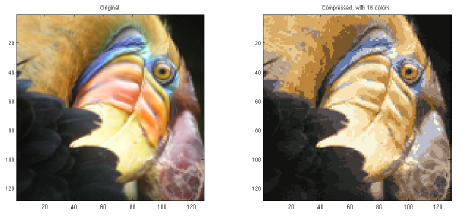

    Finally, you can view the effects of the compression by reconstructing the image based only on the centroid assignments. Specically, you can replace each pixel location with the mean of the centroid assigned to it. Figure 3 shows the reconstruction we obtained. Even though the resulting image retains most of the characteristics of the original, we also see some compression artifacts.

Essentially, now we have represented the image `X` as in terms of the indices in `idx`. We can now recover the image from the indices (`idx`) by mapping each pixel (specified by it's index in `idx`) to the centroid value.

X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square

*You do not need to make any submissions for this part of the exercise.*

### 1.5 Optional (ungraded) exercise: Use your own image

In this exercise, modify the code we have supplied to run on one of your own images. Note that if your image is very large, then *K*-means can take a long time to run. Therefore, we recommend that you resize your images to managable sizes before running the code. You can also try to vary `K` to see the effects on the compression.

## 2. Principal Component Analysis

In this exercise, you will use principal component analysis (PCA) to perform dimensionalty reduction. You will first experiment with an example 2D dataset to get intuition on how PCA works, and then use it on a bigger dataset of 5000 face image dataset. The code provided, will help you step through the first half of the exercise.

### 2.1 Example dataset

To help you understand how PCA works, you will first start with a 2D dataset which has one direction of large variation and one of smaller variation. The code below will plot the training data (Figure 4). 

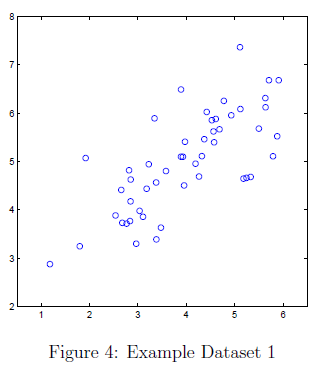

In this part of the exercise, you will visualize what happens when you use PCA to reduce the data from 2D to 1D. In practice, you might want to reduce data from 256 to 50 dimensions, say; but using lower dimensional data in this example allows us to visualize the algorithms better.

% Initialization
clear;
% The following command loads the dataset. You should now have the variable X in your environment
load ('ex7data1.mat');

% Visualize the example dataset
figure;
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;

### 2.2 Implementing PCA

In this part of the exercise, you will implement PCA. PCA consists of two computational steps: First, you compute the covariance matrix of the data. Then, you use MATLAB's `svd` function to compute the eigenvectors $U_1, U_2,\ldots,U_n$. These will correspond to the principal components of variation in the data. Before using PCA, it is important to first normalize the data by subtracting the mean value of each feature from the dataset, and scaling each dimension so that they are in the same range. In the code below, this normalization has been performed for you using the `featureNormalize` function.

    After normalizing the data, you can run PCA to compute the principal components. You task is to complete the code in `pca.m` to compute the principal components of the dataset. First, you should compute the covariance matrix of the data, which is given by:


$$\Sigma =\frac{1}{m}X^T X$$


where $X$ is the data matrix with examples in rows, and $m$ is the number of examples. Note that $\Sigma$ is a $n \times n$ matrix and not the summation operator.

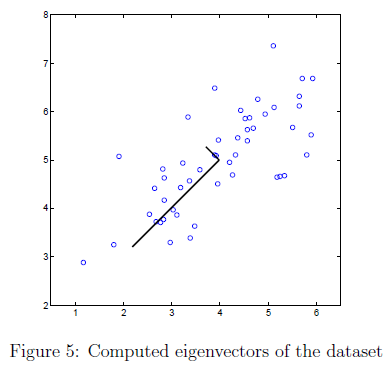

After computing the covariance matrix, you can run SVD on it to compute the principal components. In MATLAB, you can run SVD with the following command: 

where `U` will contain the principal components and `S` will contain a diagonal matrix. Once you have completed `pca.m`, the code below will run PCA on the example dataset and plot the corresponding principal components found (Figure 5). The script will also output the top principal component (eigenvector) found, and you should expect to see an output of about `[-0.707 -0.707]`. (It is possible that MATLAB may instead output the negative of this, since $U_1$ and $-U_1$ are equally valid choices for the first principal component.)

% Before running PCA, it is important to first normalize X
[X_norm, mu, ~] = featureNormalize(X);

% Run PCA
[U, S] = pca(X_norm);

% Draw the eigenvectors centered at mean of data. These lines show the directions of maximum variations in the dataset.
hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;

fprintf('Top eigenvector U(:,1) = %f %f \n', U(1,1), U(2,1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Dimensionality reduction with PCA

After computing the principal components, you can use them to reduce the feature dimension of your dataset by projecting each example onto a lower dimensional space, $x^{(i)}\rightarrow z^{(i)}$ (e.g., projecting the data from 2D to 1D). In this part of the exercise, you will use the eigenvectors returned by PCA and project the example dataset into a 1-dimensional space.

    In practice, if you were using a learning algorithm such as linear regression or perhaps neural networks, you could now use the projected data instead of the original data. By using the projected data, you can train your model faster as there are less dimensions in the input.

#### 2.3.1 Projecting the data onto the principal components

You should now complete the code in `projectData.m`. Specically, you are given a dataset `X`, the principal components `U`, and the desired number of dimensions to reduce to `K`. You should project each example in `X` onto the top `K` components in `U`. Note that the top `K` components in `U` are given by the first `K` columns of `U`, that is `U_reduce = U(:, 1:K)`.

Once you have completed the code in` projectData.m`, run the code below to project the first example onto the first dimension and you should see a value of about `1.481` (or possibly `-1.481`, if you got $-U_1$ instead of $U_1$).

% Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.2 Reconstructing an approximation of the data

After projecting the data onto the lower dimensional space, you can approximately recover the data by projecting them back onto the original high dimensional space. Your task is to complete `recoverData.m` to project each example in `Z` back onto the original space and return the recovered approximation in `X_rec`. Once you have completed the code in `recoverData.m`, the code below will recover an approximation of the first example and you should see a value of about `[-1.047 -1.047]`.

X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.3 Visualizing the projections

After completing both `projectData` and `recoverData`, the code in this section will perform both the projection and approximate reconstruction to show how the projection affects the data. In Figure 6, the original data points are indicated with the blue circles, while the projected data points are indicated with the red circles. The projection effectively only retains the information in the direction given by $U_1$.

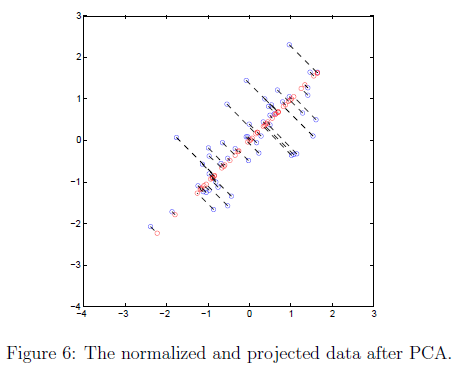

%  Plot the normalized dataset (returned from pca)
plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square
%  Draw lines connecting the projected points to the original points
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

### 2.4 Face image dataset

In this part of the exercise, you will run PCA on face images to see how it can be used in practice for dimension reduction. The dataset `ex7faces.mat` contains a dataset* `X` of face images, each $32 \times 32$ in grayscale. 

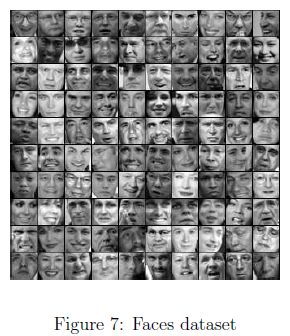

Each row of `X` corresponds to one face image (a row vector of length 1024). The code in this section will load and visualize the first 100 of these face images (Figure 7).

%  Load Face dataset
load ('ex7faces.mat')
%  Display the first 100 faces in the dataset
displayData(X(1:100, :));

**This dataset was based on a cropped version of the*[ *labeled faces in the wild dataset*](http://vis-www.cs.umass.edu/lfw/)*.*

#### 2.4.1 PCA on faces

To run PCA on the face dataset, we first normalize the dataset by subtracting the mean of each feature from the data matrix `X`. The code below will do this for you and then run your PCA code. After running PCA, you will obtain the principal components of the dataset. Notice that each principal component in `U` (each row) is a vector of length $n$ (where for the face dataset, $n = 1024$). It turns out that we can visualize these principal components by reshaping each of them into a $32 \times 32$ matrix that corresponds to the pixels in the original dataset. 

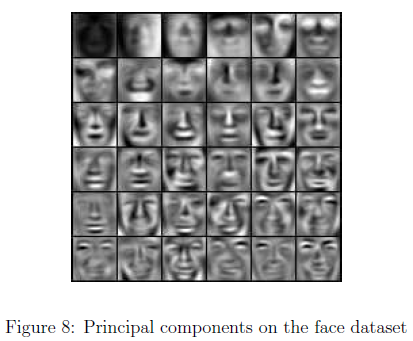

The code below displays the first 36 principal components that describe the largest variations (Figure 8).  If you want, you can also change the code to display more principal components to see how they capture more and more details. Before running PCA, it is important to first normalize `X` by subtracting the mean value from each feature.

[X_norm, ~, ~] = featureNormalize(X);

% Run PCA
[U, ~] = pca(X_norm);

% Visualize the top 36 eigenvectors found
displayData(U(:, 1:36)');

The code below will project the face dataset onto only the first 100 principal components. Concretely, each face image is now described by a vector $z^{(i)}\in\mathbb{R}^{100}$. 

K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: %d x %d', size(Z));

To understand what is lost in the dimension reduction, you can recover the data using only the projected dataset. In the code below, an approximate recovery of the data is performed and the original and projected face images are displayed side by side (Figure 9). 

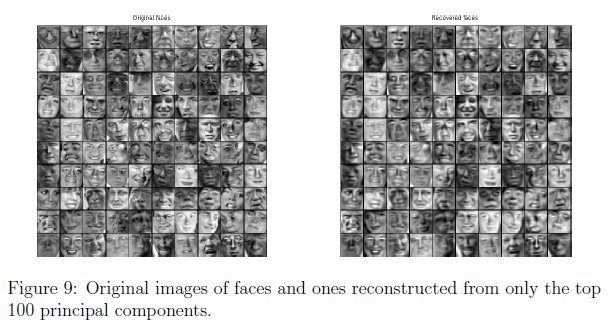

From the reconstruction, you can observe that the general structure and appearance of the face are kept while the fine details are lost. This is a remarkable reduction (more than $10\times$) in the dataset size that can help speed up your learning algorithm signicantly. For example, if you were training a neural network to perform person recognition (gven a face image, predict the identitfy of the person), you can use the dimension reduced input of only a 100 dimensions instead of the original pixels.

X_rec  = recoverData(Z, U, K);

% Display normalized data
subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

% Display reconstructed data from only k eigenfaces
subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

### 2.5 Optional (ungraded) exercise: PCA for visualization

In the earlier *K*-means image compression exercise, you used the *K*-means algorithm in the 3-dimensional RGB space. In this section, we have provided code to visualize the final pixel assignments in this 3D space using the `scatter3` function. Each data point is colored according to the cluster it has been assigned to. You can select the rotate icon and then drag your mouse on the figure to rotate and inspect this data in 3 dimensions.

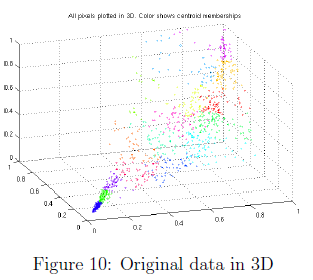

clear;
% Re-load the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));
A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');

    It turns out that visualizing datasets in 3 dimensions or greater can be cumbersome. Therefore, it is often desirable to only display the data in 2D even at the cost of losing some information. In practice, PCA is often used to reduce the dimensionality of data for visualization purposes. In the code below, the script will apply your implementation of PCA to the 3-dimensional data to reduce it to 2 dimensions and visualize the result in a 2D scatter plot. The PCA projection can be thought of as a rotation that selects the view that maximizes the spread of the data, which often corresponds to the 'best' view.

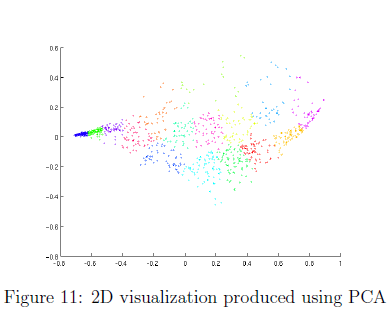

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored. 

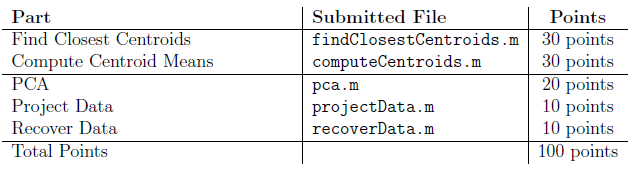

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.